# 直交基底、直交行列、Gram-Schmidtの直行化法

## 正規直交

ベクトル$q_1 \cdots q_n$は


$$q_i^T q_j \left\lbrace \begin{array}{c}
0 & i\ne j\left(\mathrm{直交ベクトル}\right)\\
1 & i=j\left(\mathrm{単位ベクトル}:\left\|q_i \right\|=1\right)
\end{array}\right.$$


## 射影と最小2乗：正規直交の場合

もし$A$の列が正規直交ならば


$$A^T A=\left\lbrack \begin{array}{c}
\cdots  & a_1^T  & \cdots \\
\cdots  & a_2^T  & \cdots \\
\cdots  & \vdots  & \cdots \\
\cdots  & a_n^T  & \cdots 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\vdots  & \vdots  & \vdots  & \vdots \\
a_1  & a_2  & \cdots  & a_n \\
\vdots  & \vdots  & \vdots  & \vdots 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1 & 0 & \cdots  & 0\\
0 & 1 & \cdots  & 0\\
\vdots  & \vdots  & \ddots  & \vdots \\
0 & 0 & \cdots  & 1
\end{array}\right\rbrack =I$$


これにより、射影行列は


$$P={\mathrm{AA}}^T ,\text{   }\overline{x} =A^T b$$


となる

## 3.3.1

A = [1,-2;1,-1;1,1;1,2]

A =        1             -2       
       1             -1       
       1              1       
       1              2       


b = [-4;-3;-1;0]

b =       -4       
      -3       
      -1       
       0       


dot(A(:,1),A(:,2))

ans =        0       



$$\begin{array}{l}
C=\frac{1}{2}c\\
c=2C\\
D=\frac{1}{\sqrt{10}}d\\
d=\sqrt{10}D
\end{array}$$


A2 = [A(:,1)*(1/4),A(:,2)*(1/10)]

A2 =        1/4           -1/5     
       1/4           -1/10    
       1/4            1/10    
       1/4            1/5     


x=A2'*b

x =       -2       
       1       



$$y=-2+t$$


t = [-2,-1,1,2]

t =       -2             -1              1              2       


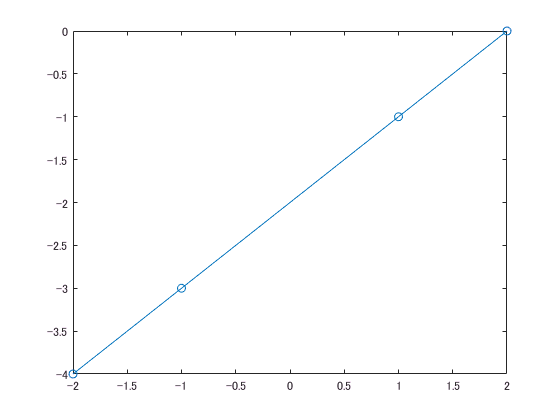

plot(t,-2+t,'-o')

A * x

ans =       -4       
      -3       
      -1       
       0       


norm(A*x-b)

ans =        0       


## 3.3.2

b = [0;3;0]

b =        0       
       3       
       0       


a1 = [2/3;2/3;-1/3]

a1 =        2/3     
       2/3     
      -1/3     


a2 = [-1/3;2/3;2/3]

a2 =       -1/3     
       2/3     
       2/3     


a1 * a1'*b

ans =        4/3     
       4/3     
      -2/3     


a2 * a2' *b

ans =       -2/3     
       4/3     
       4/3     


A = [a1,a2]

A =        2/3           -1/3     
       2/3            2/3     
      -1/3            2/3     


A * A' * b

ans =        2/3     
       8/3     
       2/3     


## 3.3.3

a3 = [2/3;-1/3;2/3]

a3 =        2/3     
      -1/3     
       2/3     


a3 * a3' * b

ans =       -2/3     
       1/3     
      -2/3     


A = [a1,a2,a3]

A =        2/3           -1/3            2/3     
       2/3            2/3           -1/3     
      -1/3            2/3            2/3     


a1 * a1'*b+a2 * a2' *b + a3 * a3' * b

ans =        0       
       3       
       0       


## 直交行列

正規直交の列を持つ正方行列


$$\begin{array}{l}
Q^{T\text{ }} Q=I\\
{\mathrm{QQ}}^T =I\\
Q^T =Q^{-1} 
\end{array}$$


## 例1


$$\begin{array}{l}
Q=\left\lbrack \begin{array}{c}
\mathrm{cos}\theta  & -\mathrm{sin}\theta \\
\mathrm{sin}\theta  & \mathrm{cos}\theta 
\end{array}\right\rbrack \\
Q^T =Q^{-1} =\left\lbrack \begin{array}{c}
\mathrm{cos}\theta  & \mathrm{sin}\theta \\
-\mathrm{sin}\theta  & \mathrm{cos}\theta 
\end{array}\right\rbrack 
\end{array}$$


## 例2

交換行列$P$は直交行列


$$\begin{array}{l}
P=\left\lbrack \begin{array}{c}
0 & 1\\
1 & 0
\end{array}\right\rbrack \\
P^{-1} =P^T =\left\lbrack \begin{array}{c}
0 & 1\\
1 & 0
\end{array}\right\rbrack 
\end{array}$$



$$\begin{array}{l}
P=\left\lbrack \begin{array}{c}
0 & 1 & 0\\
0 & 0 & 1\\
1 & 0 & 0
\end{array}\right\rbrack \\
P^{-1} =P^T =\left\lbrack \begin{array}{c}
0 & 0 & 1\\
1 & 0 & 0\\
0 & 1 & 0
\end{array}\right\rbrack 
\end{array}$$
